pyenv("Version", "/opt/anaconda3/envs/DeepMIMO/bin/python", "ExecutionMode", "OutOfProcess")

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "/opt/anaconda3/envs/DeepMIMO/bin/python"
          Library: "/opt/anaconda3/envs/DeepMIMO/lib/libpython3.11.dylib"
             Home: "/opt/anaconda3/envs/DeepMIMO"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


% Code Section: Load DeepMIMO Variables
[aoa_az, aoa_el, aod_az, aod_el, delay, power, phase, rx_pos, tx_pos, los, carrier_frequency, bandwidth] = pyrunfile("./DeepMIMO_Matlab_Integration.py", ["aoa_az", "aoa_el", "aod_az", "aod_el", "delay", "power", "phase", "rx_pos", "tx_pos", "los", "carrier_frequency", "bandwidth"]);

Scenario "asu_campus_3p5" already exists in /Users/kengminl/Desktop/DeepMIMO/deepmimo/integrations/deepmimo_scenarios
Loading TXRX PAIR: TXset 1 (tx_idx 0) & RXset 0 (rx_idxs 131931)


% Function to convert DeepMIMOArray to MATLAB array, preserving NaN values
function matlab_array = convert_deepmimo_array(py_array, array_name)
    try
        % Convert to NumPy array with float64 dtype to ensure NaN compatibility
        % *** Don't use float32 here cuz. It leads to error when running double(np_array) later on***
        np_array = py.numpy.array(py_array, dtype='float64'); 
        
        % Convert to MATLAB double
        matlab_array = double(np_array);
        
    catch e
        fprintf('Error converting %s: %s\n', array_name, e.message);
        disp(py.dir(py_array)); % List methods/attributes
        disp(py.numpy.dtype(py.numpy.array(py_array))); % Original dtype
        error('Conversion failed for %s. Try preprocessing in Python.', array_name);
    end
end

% Convert all DeepMIMO variables to MATLAB arrays
aoa_az = convert_deepmimo_array(aoa_az, 'aoa_az'); % Shape: (131931, 10)
aoa_el = convert_deepmimo_array(aoa_el, 'aoa_el');
aod_az = convert_deepmimo_array(aod_az, 'aod_az');
aod_el = convert_deepmimo_array(aod_el, 'aod_el');
delay = convert_deepmimo_array(delay, 'delay');
power = convert_deepmimo_array(power, 'power');
phase = convert_deepmimo_array(phase, 'phase');
rx_pos = convert_deepmimo_array(rx_pos, 'rx_pos'); % Shape: (131931, 3)
tx_pos = convert_deepmimo_array(tx_pos, 'tx_pos'); % Shape: (1, 3)
los = convert_deepmimo_array(los, 'los');
carrier_frequency = double(carrier_frequency)

carrier_frequency = 3.5000e+09

bandwidth = double(bandwidth)

bandwidth = 100000000

% Process data for a single user (e.g., user_idx = 1)
user_idx = 10; % Adjust as needed
aoa_az_user = aoa_az(user_idx, :); % Shape: (1, 10)
aoa_el_user = aoa_el(user_idx, :);
aod_az_user = aod_az(user_idx, :);
aod_el_user = aod_el(user_idx, :);
delay_user = delay(user_idx, :);
power_user = power(user_idx, :);
phase_user = phase(user_idx, :);
los_user = los(user_idx); % Scalar LOS status

% Map los_user to HasLOSCluster
has_los = (los_user == 1); % true if los_user is 1, false if -1 or 0
fprintf('User %d LOS status: %d (HasLOSCluster: %d)\n', user_idx, los_user, has_los);

User 10 LOS status: 0 (HasLOSCluster: 0)



% Filter out NaN values (valid paths)
valid_paths = ~isnan(power_user); % Logical array for non-NaN paths
num_paths = sum(valid_paths); % Number of valid paths
if num_paths == 0
    warning('No valid paths for user %d. Skipping.', user_idx);
    return;
end

% Extract valid path parameters
aoa_az_valid = aoa_az_user(valid_paths); % Azimuth AoA (degrees)
aoa_el_valid = aoa_el_user(valid_paths); % Elevation AoA (degrees)
aod_az_valid = aod_az_user(valid_paths); % Azimuth AoD (degrees)
aod_el_valid = aod_el_user(valid_paths); % Elevation AoD (degrees)
delay_valid = delay_user(valid_paths); % Delays (seconds)
power_valid = power_user(valid_paths); % ***check whether change to dB*** Convert to dB
phase_valid = phase_user(valid_paths); % Phases (radians)

% Debug: Display valid paths
fprintf('User %d: %d valid paths\n', user_idx, num_paths);

User 10: 10 valid paths


disp('Valid aoa_az:'); disp(aoa_az_valid);

Valid aoa_az:
   40.3789   34.8127  140.9200  146.4880   40.2582   34.8937  141.0410   90.6498  100.6840   90.6870



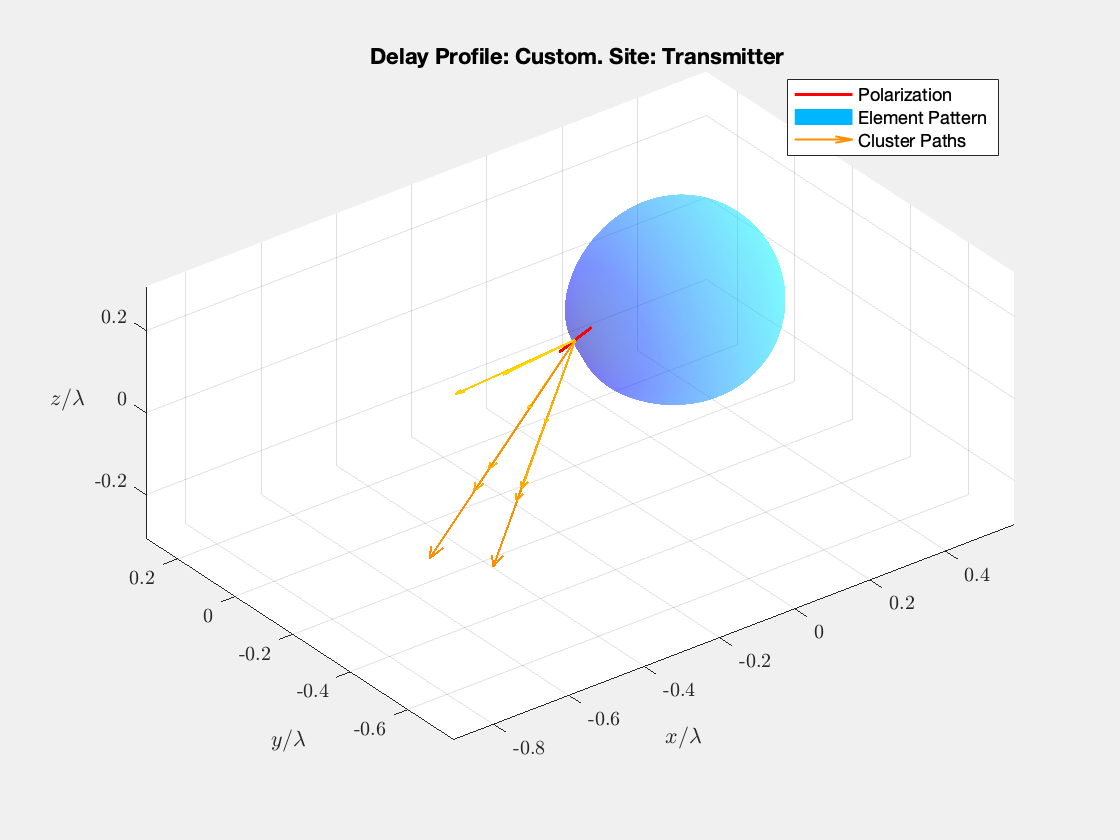

% Initialize nrCDLChannel
cdl = nrCDLChannel;
cdl.DelayProfile = 'Custom'; % Use custom delay profile

% Set path parameters
cdl.PathDelays = delay_valid; % Path delays (seconds)
cdl.AveragePathGains = power_valid; % Path gains (dB)
cdl.AnglesAoA = aoa_az_valid; % Azimuth AoA (degrees)
cdl.AnglesZoA = 180 - aoa_el_valid; % Zenith AoA (degrees)
cdl.AnglesAoD = aod_az_valid; % Azimuth AoD (degrees)
cdl.AnglesZoD = 180 - aod_el_valid; % Zenith AoD (degrees)

% LOS detection
cdl.HasLOSCluster = has_los; % Set from los_user

% Channel configuration
cdl.CarrierFrequency = carrier_frequency; % 3.5 GHz
cdl.SampleRate = bandwidth
cdl.NormalizeChannelOutputs = false; % do not normalize by the number of receive antennas, this would change the receive power
cdl.NormalizePathGains = false;      % set to false to retain the path gains
cdl.MaximumDopplerShift = 0; % Static scenario


% Antenna configuration
cdl.TransmitAntennaArray.Size = [1, 1, 1, 1, 1];
cdl.ReceiveAntennaArray.Size = [1, 1, 1, 1, 1];

% displayChannel(cdl,'LinkEnd','Tx');

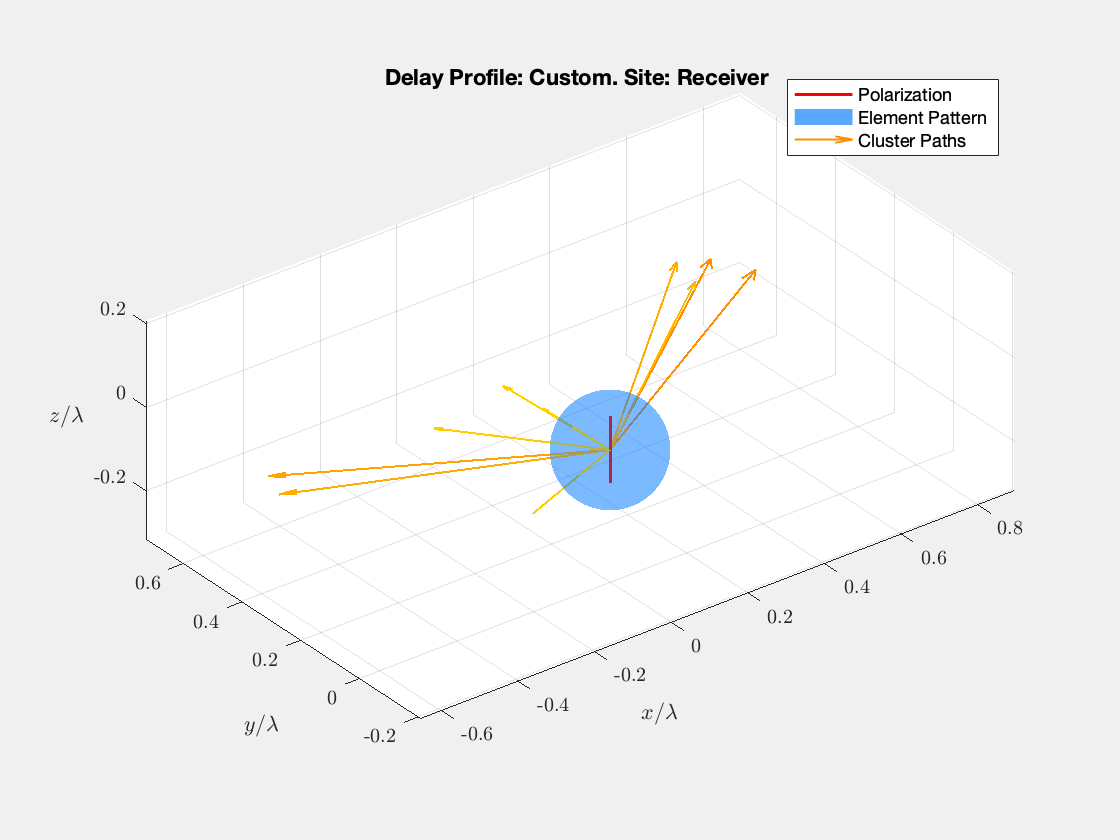


% displayChannel(cdl,'LinkEnd','Rx');

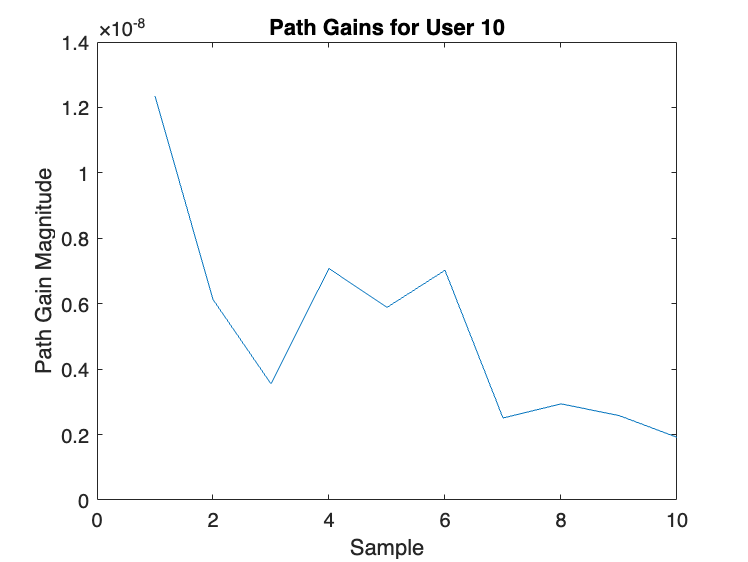

% Create a random input waveform
cdl_info = info(cdl);
Nt = cdl_info.NumTransmitAntennas;
T = cdl.SampleRate * 1e-3; % 1 ms
txWaveform = complex(randn(T, Nt), randn(T, Nt));

% Pass through channel
[rxWaveform, pathGains] = cdl(txWaveform);

% Plot path gains
figure;
plot(abs(pathGains));
xlabel('Sample'); ylabel('Path Gain Magnitude');
title(sprintf('Path Gains for User %d', user_idx));